# Copy Data

Enter required information in the edit fields and drop down menus.

Click "*Copy Data*" button to process and copy data from the *s.directory* to *mylocation. *

The copy execution can take sometime (~30mins) due to large file sizes.

% enter PDGS_NAS_folder FTP location and connect to it
s.host = "kiteworks.sstl.co.uk";
s.user = "hydrognss_user@sstl.co.uk";
s.pass = "WhiskyLazyCrates6$*%";
s.directory = "public";
sftpobject = sftp(s.host,s.user,'Password',s.pass,...
    'ServerLocale','en_GB',DirParserFcn=@parseServerData); 

% enter location to copy data to
mylocation = "C:\SSTL\Temp\MatlabDownload"

mylocation = "C:\SSTL\Temp\MatlabDownload"


% list folders in the "public" directory, parse dir list 
% accordingly
out = dir(sftpobject,fullfile(s.directory));
satellites = string(({out(:).name})');
% Choose Satellite
sat = satellites(2)

sat = "HydroGNSS-1"


% Choose Processor
out = dir(sftpobject,strrep(fullfile(s.directory,sat),...
    '\','/'));
processors = string(({out(:).name})');
proc = processors(1)

proc = "L1A_L1B"


% Choose Month
out = dir(sftpobject,strrep(fullfile(s.directory,sat,proc),...
    '\','/'));
months = string(({out(:).name})');
mon = months(1)

mon = "2018-02"


% Choose Date
out = dir(sftpobject,strrep(fullfile(s.directory,sat,proc,...
    mon),'\','/'));
dates = string(({out(:).name})');
day = dates(20)

day = "24"


% Choose 6-Hour Block
out = dir(sftpobject,strrep(fullfile(s.directory,sat,proc,...
    mon,day),'\','/'));
hours = string(({out(:).name})');
hour = hours(2)

hour = "H06"


% files
sixhourblock = strrep(fullfile(s.directory,sat,proc,mon,...
    day,hour),'\','/');


%% copy selected data to mylocation
 

disp('Copying Data')

Copying Data


mget(sftpobject,sixhourblock, fullfile(mylocation));
% check data is present
if isfolder(fullfile(mylocation,s.directory,sat,proc,mon,...
        day,hour))
    disp('Directory Copied.')
else
    error('Directory not found.')
end

Directory Copied.


## Extract, Filter and Plot L1B Example

Click the "*Extract and Plot Example*" button to extract, filter and plot the L1B data selected in the edit fields.

%% Extract and Plot data?
 

% readL1merged concatenates all chanels in to one array. 
% All information is retained and can be filtered by any other data point,
% SNR for example.
if strcmp(proc,'L1A_L1B')
    
    % read data (please wait)
    l1bData = readL1merged(fullfile(mylocation,s.directory,sat,proc,...
        mon,day,hour,'metadata_L1_merged.nc'));
    % choose field
    l1bfields = string(fieldnames(l1bData));
    l1bfield = l1bfields(7)
    % choose parameter
    l1bparameters = string(fieldnames(l1bData.(l1bfield)));
    parameterX = l1bparameters(1)
    parameterY = l1bparameters(24)
    dataX = l1bData.(l1bfield).(parameterX);
    dataY = l1bData.(l1bfield).(parameterY);  

### Filter Data

    % Pick a filter and limit
    parameterFilt = l1bparameters(17)
    dataFilt = l1bData.(l1bfield).(parameterFilt);
    limit = 0

    l1bfilter = dataFilt > limit;

### Plot Data

Reading L1merged...
Finished Reading L1merged.


l1bfield = "IncoherentChan1"

parameterX = "IntegrationMidPointTime"

parameterY = "ReflectionCoefficientAtSP"

parameterFilt = "DDMSNRAtPeakSingleDDM"

limit = 0

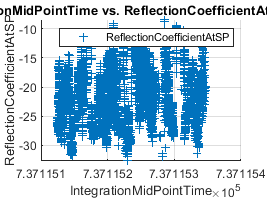

    % Create scatter of dataX and dataY
    sfig = scatter(dataX(l1bfilter),dataY(l1bfilter),'Marker',...
        '+','DisplayName',parameterY);
    
    % Add xlabel, ylabel, title, and legend
    xlabel(parameterX)
    ylabel(parameterY)
    title(sprintf('%s vs. %s Filtered',parameterX,parameterY))
    grid on
    legend

end

### Parse Function for Server Output

function listing = parseServerData(entries,serverLocale, ~)
% Parse server data in string array
    entries = regexprep(entries,' *',' '); % remove multiple white spaces
    out = split( entries , ' ' ,2); % split into columns
    [structSize,~] = size(out);
    % form dir struct    
    listing = struct("name",cell(structSize,1),"isdir",zeros(1,1), ...
        "bytes",zeros(1,1),"date",'',"datenum",zeros(1,1));
    monthName = string(out(:,end-2));
    day = string(out(:,end-3));
    time = string(out(:,end-1));
    names = string(out(:,end));
    bytes = string(out(:,end-4));
    for ii = 1 : structSize
        listing(ii).name = names{ii};
        listing(ii).isdir = false;
        listing(ii).bytes = bytes(ii);
        makeDate = day(ii) + "-" + monthName(ii) + " " + ...
            time(ii);
        thisDate = datetime(makeDate, "InputFormat", "dd-MMM HH:mm", ...
            "Locale", serverLocale);
        listing(ii).date = datestr(thisDate);
        listing(ii).datenum = datenum(thisDate);    
    end
end